# Visualization CMTF-PT2

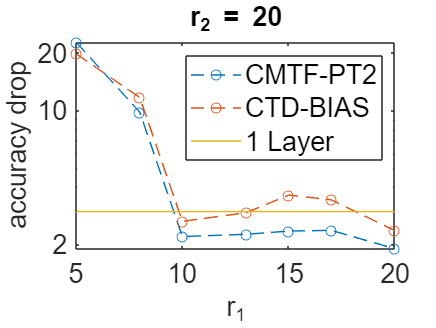

L1data = [20 17 15 13 10 08 05];%     15 15 15 15    10 10 10 10    05 05 05 05];
L2data = [20 17 15 13 10 08 05];%     20 15 10 05    20 15 10 05    20 15 10 05];

AccDropData = 97.1 - [95.2 94.73 94.75 94.84 94.90 87.31 74.38
    94.70 94.32 93.10 94.59 93.92 87.54 76.98  
    94.00 93.47 94.05 93.78 93.20 85.93 67.83   
    93.56 93.04 93.50 90.93 90.89 81.73 73.35  
    92.32 91.68 91.37 92.01 90.79 85.49 67.50
    86.29 86.30 86.39 85.39 81.03 81.83 70.51
    71.13 70.48 68.16 66.85 65.73 66.66 64.80];

JErrData = [0.4055 0.4259 0.4292 0.4464 0.4305 0.4609 0.5443
    0.4376 0.4463 0.4571 0.4476 0.4703 0.4783 0.5547
    0.4600 0.4577 0.4656 0.4618 0.4743 0.4967 0.5690
    0.4778 0.4554 0.4555 0.4877 0.4907 0.4985 0.5829
    0.4794 0.4860 0.4923 0.5042 0.5057 0.5226 0.5996
    0.5224 0.5308 0.5381 0.5320 0.5438 0.5599 0.6052
    0.6098 0.6150 0.6144 0.6193 0.6227 0.6253 0.6428];

FErrData = [0.3035 0.3247 0.3124 0.3391 0.3147 0.3942 0.5653
    0.2981 0.3158 0.3463 0.3460 0.3692 0.4110 0.5812
    0.3298 0.3287 0.3541 0.3509 0.3848 0.4138 0.5868
    0.3568 0.3579 0.3572 0.4078 0.4202 0.4635 0.6056
    0.3738 0.3886 0.4079 0.4030 0.4501 0.4518 0.6313
    0.4374 0.4477 0.4533 0.4522 0.4740 0.4794 0.6562
    0.5926 0.5878 0.6057 0.6105 0.6300 0.6483 0.6759];

%surf(L1data, L2data, AccDropData);

%surf(L1data, L2data, JErrData);

%surf(L1data, L2data, FErrData);

figure
semilogy([5 8 10 13 15 17 20], flip(AccDropData(1,:)), '--o')
hold on
semilogy([5 8 10 13 15 17 20],97.1 -[77.34 85.42 94.46 94.17 93.48 93.68 94.74], '--o')
semilogy([5 20], [2.97 2.97], '-')
ax = gca;
ax.FontSize = 16;

xlabel("r_1", "FontSize", 16)
ylabel("accuracy drop", "FontSize", 16)

legend("CMTF-PT2", "CTD-BIAS", "1 Layer", "FontSize", 16)
title("r_2 = 20", "FontSize", 16)

yticks([0.5 1 2 10 20])
hold off

clf

## Compression ratio

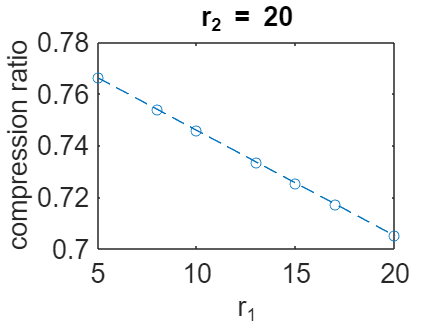

compressed = [80 20 5 10
    80 20 8 10
    80 20 10 10
    80 20 13 10
    80 20 15 10
    80 20 17 10
    80 20 20 10];
not_compr = [80 60 40 10];

compressions = [];
for i=1:size(compressed, 1)
    comp = compressed(i,:);
    compressions(i) = compression_rate(comp, not_compr, 20, comp(3));
end

figure(10)

plot(compressed(:,3), compressions, '--o')
ax = gca;
ax.FontSize = 16;
xlabel("r_1", "FontSize", 16)
ylabel("compression ratio", "FontSize", 16)
title("r_2 = 20", "FontSize", 16)

clf

## Visualization CTD-BIAS

test

## Visualization CPD-CMTF

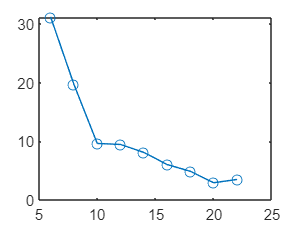

Ldata = [22 20 18 16 14 12 10 8 6];
JErrData = [0.4526 0.4602 0.4795 0.4937 0.7825 0.8024 0.6273 0.7347 0.8320];
FErrData = [0.3931 0.4070 0.4444 0.4660 0.4607 0.4422 0.3868 0.4508 0.5797];
AccDropData = 97.10 - [93.60 94.16 92.22 91.06 89.00 87.64 87.47 77.43 65.94];


plot(Ldata, AccDropData, '-o')

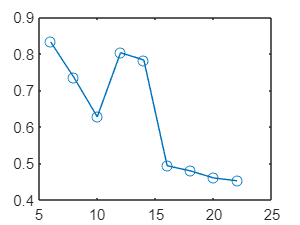

plot(Ldata, JErrData, '-o')

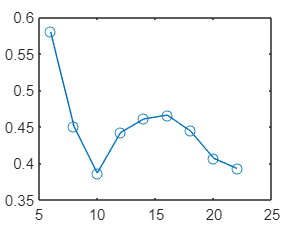

plot(Ldata, FErrData, '-o')

function [rate] = compression_rate(nodes1, nodes2, d1, d2)
    rate1 = 0;
    for i=1:size(nodes1,2)-1
        rate1 = rate1 + nodes1(i) * nodes1(i+1);
    end
    rate1 = rate1 + d1 + d2 + 2;
    
    rate2 = 0;
    for i=1:size(nodes2,2)-1
        rate2 = rate2 + nodes2(i) * nodes2(i+1);
    end

    rate = 1 - rate1 / rate2;
end